# Basics of Scripting

## Section 1: Navigating Matlab

By default, Matlab is broken into five separate boxes:

**Command window: **Running basic commands, displaying output etc. 

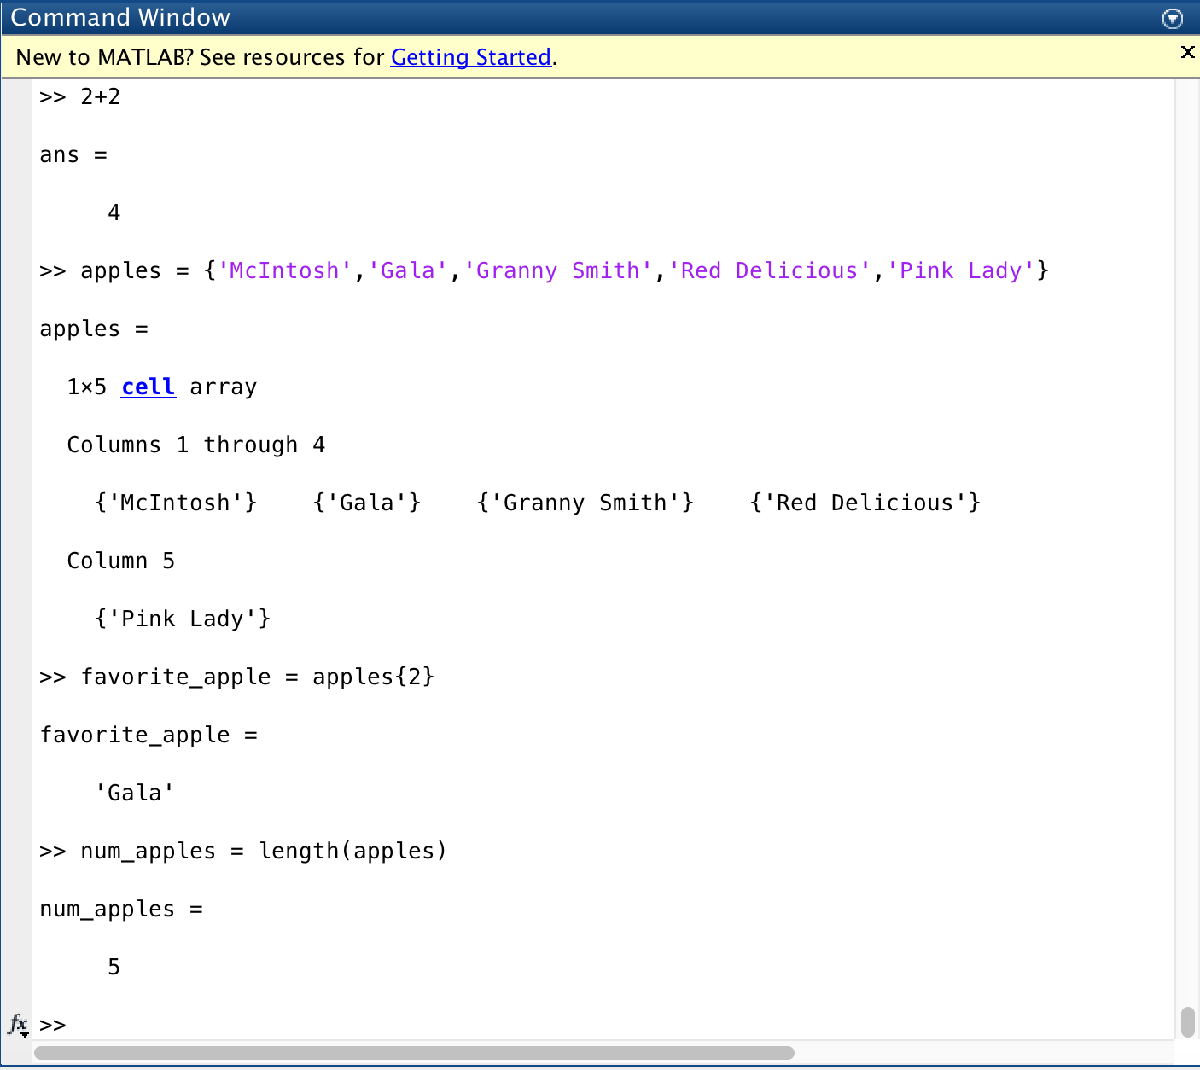

**Workspace: **View variable names, values, types, sizes.

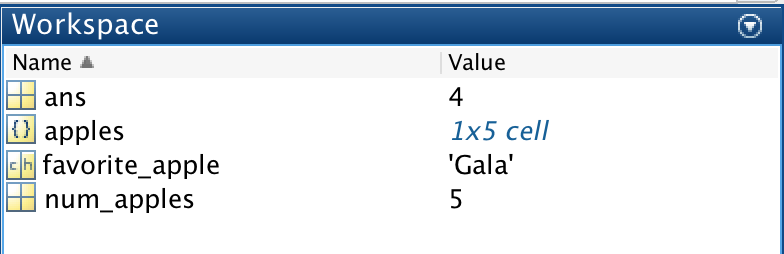

**Editor: **Writing, debugging scripts.

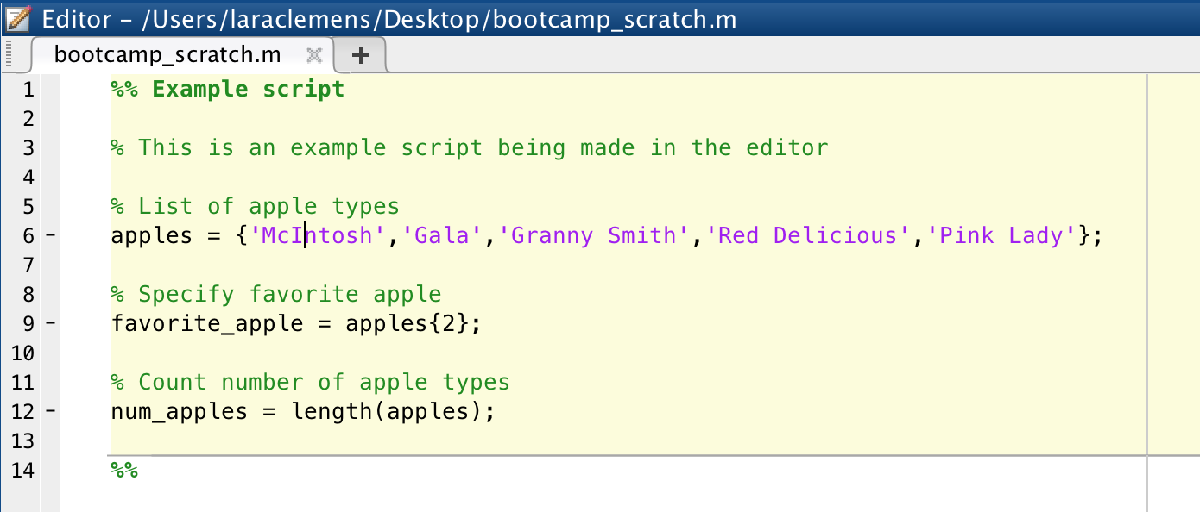

**Current folder: **Folder navigation system. 

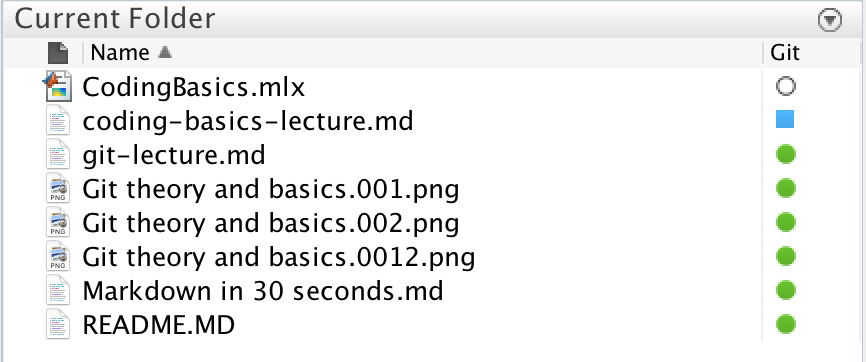

**Details: **View details of script selected in Current Folder window, including section headers.

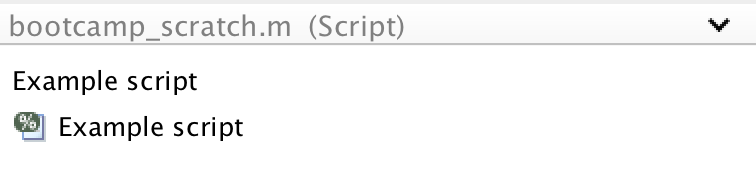

Each of these can be resized, dragged to a new position, or moved to it's own window (undocked). 

You can choose what works for you.

## Section 2: Variables

**Subsection 2.1: Math in the command window**

Working in the command window, try the following:


$$123 + 987$$



$$551/17$$



$$4-6/2$$


(551/17)+sin(551/17)/4 - (551/17)^(-2/3)

**Subsection 2.2: Variables**

Often calculations are simpler if you can store values somewhere. This let's you use the same number multiple times, store values for future use, creates more readable expressions, change a number in a single location rather than everywhere it's used etc

Matlab stores variables with '=':

x = 5

time = 10

n_people = 7.7e9

Variables names always go to the left of the expression:

vel = 4 <- WORKS

4 = vel <- DOES NOT WORK

**Subsection 2.3: Naming variables**

There are some hard rules and some soft rules regarding variable names:

- variable names must begin with a letter (not a number,symbol)

- cannot contain spaces (can use underscores, camel case)

- Note: uppercase and lowercase letters are distinct

Variable names are something you should think a lot about. Some rules of thumb:

- helps to be descriptive (e.g. num_people vs n)

- pick a convention and stick with it (e.g. always starting with lowercase, using all capitals for variables that shouldn't change, etc)

- avoid names of Matlab functions (e.g. sqrt, sin)

- avoid names of pre-existing variables, unless on purpose (e.g. pi, i, eps, are already defined in Matlab)

Some names are protected by Matlab. These will turn blue before you try to assign it:

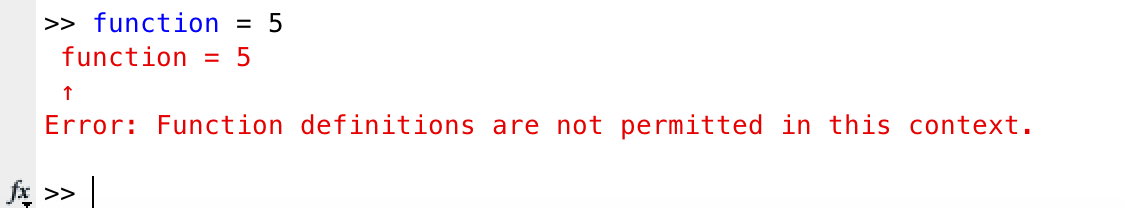

**Subsection 2.4: Clearing variables**

Sometimes it is helpful to clear a variable.

To clear just variables:

Clears all variables: 

clearvars

Clears only those specified: 

clearvars variable1 variable2

To clear more than just variables (see Matlab documentation for [clear](https://www.mathworks.com/help/matlab/ref/clear.html)):

clear (or clear all)

clear variable1 variable2

## Section 3: Scripts, Functions

**Subsection 3.1: Scripts (.m)**

Scripts can be used to save work, run lots of commands at once, debug, create functions, etc.

Scripts are the default file for writing code in Matlab. Scripts simply run what is written. 

All variables are *global, *and are not cleared unless specified by user. 

**Subsection 3.1: Functions (.m)**

Functions can take an input and return an output. Used if a section of code will be used many times. 

All variables defined in the function are *local* and cannot be seen by an encapsulating script. This is generally viewed as safer than the global variables of scripts - they won't get overwritten, used unexpectedly etc.

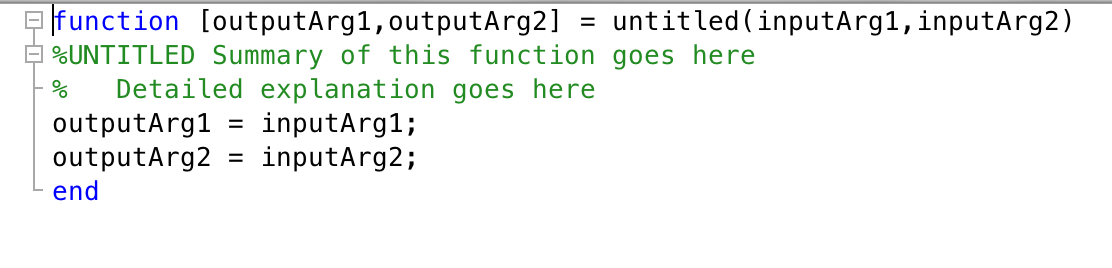

**Subsection 3.2: Live scripts (.mlx)**

Live scripts (like this one) can be used to include plain text, latex equations, and images along with the code. It will also display output in-line or to the side when each section is run.

This is particularly useful for documentation and teaching. 

Drawbacks of live scripts:

- They are slower than plain scripts.

- Github, git reads the live script as a binary file - it will not show you line-by-line changes.

- Still new - older Matlab versions limit capabilities, making sharing with collaborators harder.

## Section 4: Commenting

All code needs comments. At the top of each script, there should be a description of the goal of the script. In the rest of the code, the comments should describe what a line or piece of code is meant to do in plain words. In Matlab, commenting is done with percent signs. Comments are denoted in green text. 

% This is a comment. 

In a standard script, exactly two percent signs will create a section. Sections improve code readability and allow you to run chunks of the code at a time, instead of the whole script. 

In a live script, sections also exist, but not within the code blocks seen here. Instead, two percent signs in the text areas will create a new section.

%% Exactly two percent signs can be used to make a section in a standard script. 

## Section 5: If Statements

If statements are a way to do something conditionally. Accepts logical '1' (true) or '0' (false). If/Else statements follow the structure "If this, then do this. Otherwise, do this other thing." 

% If hungry, feed the cookie monster
hungryTF = 1;
if(hungryTF)
    disp('Fed the cookie monster a cookie!');
    hungryTF = 0;
end

% Display if x is divisible by 9
x = 54;
if(mod(x,9) ~= 0)
    disp('x is not divisible by 9');
else
    disp('x is divisible by 9');
end

Fed the cookie monster a cookie!


There are also ways to address many possible conditions. If/ElseIf/Else statements and Switch statements are good for this. If/ElseIf works for inequalities and other such operators, whereas Switch works on specific values (numbers, strings etc).

% produce random number uniformly distributed from 0 to 1
randUnif = rand;
% initialize bins
count75 = 0;
count50 = 0;
count25 = 0;
count00 = 0;

x is divisible by 9



% decide which bin randUnif should go in
if(randUnif >= 0.75)
    count75 = count75+1;
elseif(randUnif >= 0.5)
    count50 = count50+1;
elseif(randUnif >= 0.25)
    count25 = count25+1;
else
    count00 = count00+1;
end

% Create switch based on which apple is requested
requestedApple = 'Cortland'

switch requestedApple
    case 'Honeycrisp'
        disp('These are expensive!');
        
    case {'Gala','Cortland','Braeburn','Empire'}
        disp('Good Choice!');
        
    case 'Red Delicious'

requestedApple = 'Cortland'

        disp('You heathen!');
        
    case 'Granny Smith'
        disp('Buy some caramel too!');
        
    otherwise
        disp('Out of stock - pick something else!');
        
end

Good Choice!


## Section 6: For Loops

For loops are good for doing the same task over and over again, or for many different values.


% create loop to print numbers 1 through 10
for i = 1:10
    disp(i);
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10




% create loop to sum numbers -5 to 45
x = 0;
for i = -5:45
    x = x+i;
end
disp(x);

        1020



## Section 7: While Loops

While loops are good for tasks that need to be done an unknown number of times. They follow the structure '*While *this is true, do this.'

x = 1.5;
count = 0;
% while x is less than 10000, square x.
while x<10000
    x = x^2;
    count = count+1;
end
disp(count);

     5



disp(x);

   4.3144e+05



This while loop clearly works. But what happens if you choose a different value for x? Try the while loop with $0 < x <= 1$. What happens?

**Note: To 'kill' Matlab scripts, use 'Crtl-c'**

For while loops, it's best practice to include a 'dummy switch' to kill the loop after some max number of iterations. This prevents your task from running infinitely many times. This can be included using logical operators in the while loop command. 

To run script below, change if-statement to if(1). This is an easy way to not run a block of code without commenting it out.

if(1)
    x = 0.5;
    count = 0;
    countMax = 1e4; % set max iterations to 10^4
    % while x is less than 10000 AND count less than max count
    while (x<10000 && count < countMax) %&& is logical and
        x = x^2;
        count = count+1;
    end
    if(count>=countMax)
        disp(count);
        disp(x);
        error('Max counts reached!'); % end script if max counts reached
    else 
        disp(count);
        disp(x);
    end
end

       10000



     0



Max counts reached!

## Section 8: Vectors, Matrices, Indexing

It's often convenient to have groups of numbers, or many values for the same property, and to be able to manipulate them all at once. Vectors and matrices are used to store many values in the same variable name. Vectors are used to store a single list of numbers, whereas matrices are used to store several dimensions of values.

**Subsection 8.1: Vectors**

When creating vectors, they can be either horizontal or vertical, depending on what delimiter is used. Commas, or spaces, create a horizontal (row) vector. Semi-colons create a vertical (column) vector. To construct a vector, use square brackets to contain the values.

% example vectors
vec_horiz = [1, 2, 3, 4] % this is a horizontal vector

vec_horiz =      1     2     3     4


vec_vert = [1; 2; 3; 4] % this is a vertical vector

vec_vert =      1
     2
     3
     4


% ways to auto-create vectors
% default is row vector
vec_evens = 0:2:100 % create a vector from 0 to 100 by 2s

vec_evens =      0     2     4     6     8    10    12    14    16    18    20    22    24    26    28    30    32    34    36    38    40    42    44    46    48    50    52    54    56    58    60    62    64    66    68    70    72    74    76    78    80    82    84    86    88    90    92    94    96    98


vec_lin = linspace(0,1,50) % create vector from 0 to 1 with 50 evenly spaced points

vec_lin =          0    0.0204    0.0408    0.0612    0.0816    0.1020    0.1224    0.1429    0.1633    0.1837    0.2041    0.2245    0.2449    0.2653    0.2857    0.3061    0.3265    0.3469    0.3673    0.3878    0.4082    0.4286    0.4490    0.4694    0.4898    0.5102    0.5306    0.5510    0.5714    0.5918    0.6122    0.6327    0.6531    0.6735    0.6939    0.7143    0.7347    0.7551    0.7755    0.7959    0.8163    0.8367    0.8571    0.8776    0.8980    0.9184    0.9388    0.9592    0.9796    1.0000


**Subsection 8.2: Matrices**

Matrices can have multiple dimensions. Matrices are written row by row, with each row separated by a semi colon.

% example matrix
mat = [1 2 3; 4 5 6; 7 8 9; 10 11 12]

mat =      1     2     3
     4     5     6
     7     8     9
    10    11    12


The size of a matrix is described by $n$ values, where $n$ is the number of dimensions the matrix has. For a two-dimensional matrix, the first value indicates the number of rows, and the second value indicates the number of columns. A vector will also be described by two values, where one of the values is 1, depending on if it's a row or column vector.

% find the size of a matrix
mat_size = size(mat)

mat_size =      4     3


vec_horiz_size = size(vec_horiz)

vec_horiz_size =      1     4


vec_vert_size = size(vec_vert)

vec_vert_size =      4     1


**Subsection 8.3: Indexing**

To find the different values of a vector or matrix, you need to give the location, or *index,* of where you want to look. **Note: Indexing in Matlab begins at 1 and NOT 0. **Therefore, a vector with four values is indexed with 1,2,3,4. 

% display the size of the vector
size(vec_lin)

ans =      1    50



% set r to the 10th value of the vector
r = vec_lin(10)

r = 0.1837

The index also must be within the bounds of the vector or matrix. If you have a vector with ten values, you cannot access the 11th value (in Matlab anyway). What happens if you try to access something outside of these bounds?

%s = vec_lin(0)
%t = vec_lin(58)


For a matrix, indexing works the same but now you can describe the location with two values instead of one. The **first value describes the row** and the **second describes the column**.

% create a random matrix of size 4x6
mat_rand = rand(4,6)

mat_rand =     0.1626    0.3404    0.2551    0.9593    0.2575    0.2435
    0.1190    0.5853    0.5060    0.5472    0.8407    0.9293
    0.4984    0.2238    0.6991    0.1386    0.2543    0.3500
    0.9597    0.7513    0.8909    0.1493    0.8143    0.1966



% access the value in the 3rd row, 2nd column
m = mat_rand(3,2)

m = 0.2238

What happens if you give it only one dimension instead of two?

% access the 8th value of the matrix
n = mat_rand(8)

n = 0.7513

%access multiple elements
row_3 = mat_rand(3,:)

row_3 =     0.4984    0.2238    0.6991    0.1386    0.2543    0.3500


h=mat_rand(3,[2,5])

h =     0.2238    0.2543


**Subsection 8.4: Math with Vectors and Matrices**

Matlab's particular specialty is working with matrices. Hence the name MATrix LABoratory. There are two types of math that can be performed: matrix math and component-wise math.

Matrix math uses the standard operator notation: **+,-,*,/,^**

% standard matrix math - use matrix multiplication
A = 2*eye(2,2)+1 %eye is identity matrix 

A =      3     1
     1     3


x = [4; 5]

x =      4
     5


y = [4,5]

y =      4     5


b = A*x

b =     17
    19



% try out the other standard operations (+,-,^,/) on combinations of A, x, y to see what they do
b = A-y

b =     -1    -4
    -3    -2


b = A/A

b =     1.0000   -0.0000
         0    1.0000


b = (A)^2

b =     10     6
     6    10


Component-wise math uses 'dot notation':  **.*, ./, .^**

Note that adding and substracting are always component-wise, so there is no need for dot notation with those operations.

% component-wise math
disp(A);

     3     1
     1     3



disp(x);

     4
     5



disp(y);

     4     5



% try out component-wise operators
b = A.*x

b =     12     4
     5    15


b = A./y

b =     0.7500    0.2000
    0.2500    0.6000


b = A.^2

b =      9     1
     1     9


Note that many for-loops can be replaced by matrix math in Matlab. Matlab is particularly good at matrix math, so this is also faster.


% using for loops to multiply C and k component-wise, put answer in D
C = ones(4,100)

C =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1   

k = [4; 5; 6; 7]

k =      4
     5
     6
     7


D = zeros(size(C));
for i=1:size(C,1)
    for j= 1:size(C,2)
        D(i,j) = C(i,j)*k(i);
    end
end
disp(D);

  Columns 1 through 15

     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4
     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5
     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6
     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7

  Columns 16 through 30

     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4
     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5
     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6
     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7

  Columns 31 through 45

     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4
     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5
     6     6  


% using .* notation
D_dot = C.*k

D_dot =      4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4
     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5
     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6
     7     7     7     7     7     7     7     7     7     7     7     7     7     7     

% show non-zero values of D-D_dot (where D ~= D_dot)
find(D-D_dot)


ans =

  0×1 empty double column vector



Note: the for loop version will work if k is a row or column vector. The dot notation will only work if the dimensions agree with the matrix (here, if k is a column vector). If your matrix is *square* (same number of rows and columns), take care to multiply the correct direction - over rows or over columns.

## Section 9: Plotting

Visualizing data and functions is important for explaining and understanding models, results, and trends. Matlab has a very basic way to plot:

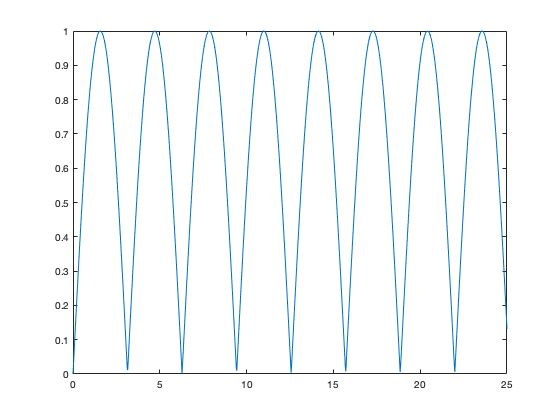

% create some data to plot
x_data = linspace(0,25,1000);
y_data = abs(sin(x_data));

% plot
figure;
plot(x_data,y_data);

How can we make this plot nicer?

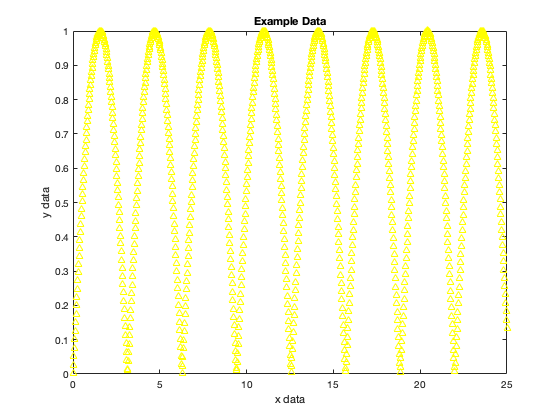

figure('Name','Example data'); 
plot(x_data,y_data,'^y'); % ^ denotes a possible marker style (triangles), m indicates preset color (magenta)
xlabel('x data');
ylabel('y data');
title('Example Data');

What about plotting multiple datasets on the same graph?

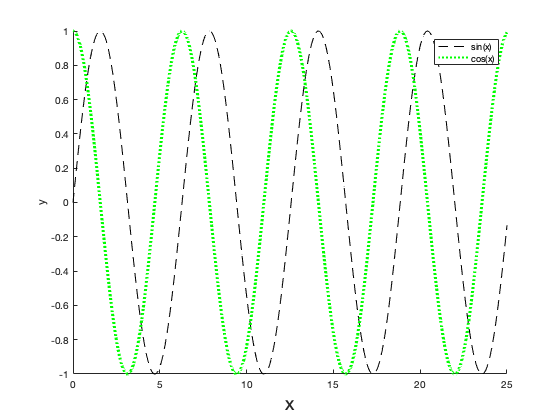

% plot sin(x), cos(x) on same axes -- hold on keeps plots together -- Name
% not in livescript
figure('Name','Sin(x) and Cos(x)'); hold on; 
pSin = plot(x_data,sin(x_data),'LineStyle','--','Color','k'); % could equivalently write plot(x_data,sin(x_data),'--k');
pCos = plot(x_data,cos(x_data),':g');
pCos.LineWidth = 2; % could use 'LineWidth',2 in plot() instead
xlabel('x','FontSize',18);
ylabel('y');
legend('sin(x)','cos(x)');

The command '[hold](https://www.mathworks.com/help/matlab/ref/hold.html) on' means any new plots will end up on same figure without overwriting. This will continue until 'hold off' is called, or until a new figure is called.

Assigning a plot to a variable is called a 'plot handle'. You can make many manipulations after the fact if you've saved the plot handle. It's also an alternate way to make property changes without having a very long single line of code. Similarly, you can save figure or axes handles.

Figures in Matlab are infinitely customizable with varying levels of ease.

Some other helpful ways to customize:

- xlim, ylim - set limits for axes

- xtick, ytick - set where axes ticks should occur

- set Position - set position on screen and size of a figure or axes within a figure

- [List of line properties](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.line-properties.html)

- [List of axes properties](https://www.mathworks.com/help/matlab/ref/matlab.graphics.axis.axes-properties.html)

There are many other [types of plots](https://www.mathworks.com/help/matlab/creating_plots/types-of-matlab-plots.html) that are useful:

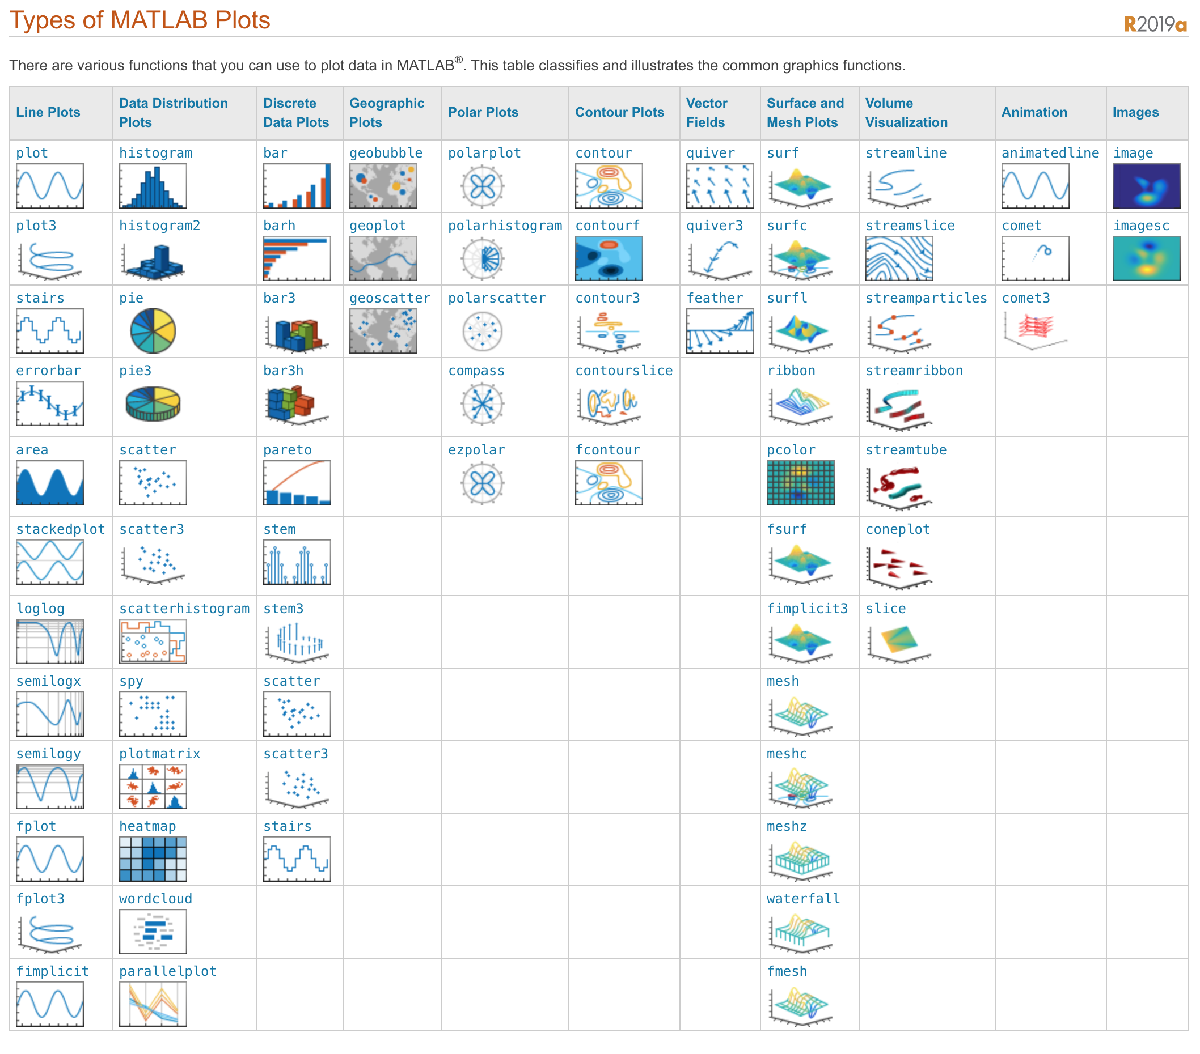

## Section 10: Save, Load

Saving data or figures in matlab is easy. 

For data, it's particularly convenient for scripts that take a long time to run, a way to save progress, or for data you need to use many times in other scripts. 

For figures, it's a nice way to automatically save your figures in a specific format to a specific location.

% saving data

% create some data to save
t_data = linspace(0,24,100);
temperature_data = -8*cos((t_data-3)/4)+70;

% plot data
fig_weather = figure; clf; 
plot(t_data,temperature_data,'-r','DisplayName','temperature');
xlabel('time (hr)');
ylabel('temperature (\circ F)');
title('Typical SoCal Weather Over a Day')


% this saves entire workspace as .mat file
% give a full file path to send the file to a location other than your current directory
% data should not be saved in your git repository
% in general, don't save it to your desktop either - pick a smart place for it
% NOTE: YOU WILL NEED TO CHANGE THE FILEPATH (~/Desktop/) TO YOUR FOLDER FOR THIS TO WORK
save('~/Desktop/CodingBasics_Example.mat'); %saves EVERYTHING

% this saves specific variables
save('~/Desktop/SoCalWeather.mat','t_data','temperature_data'); %only saves 't_data','temperature_data'



By default, if a .mat file exists with the same name, then saving to it will overwrite the file. If instead, you want to append new variables, or overwrite specific variables, there is an option for that:

% create more data to save
precipitation_data = zeros(size(t_data));

% this appends data
save('~/Desktop/SoCalWeather.mat','precipitation_data','-append');

% plot this data too
figure(fig_weather); hold on;
yyaxis right; % creates second y-axis on the right
plot(t_data,precipitation_data,'ob','DisplayName','precipitation');
ylabel('precipitation (mm)')
legend('Location','southeast');


To save a figure, you need to specify the figure with a figure handle, or 'gcf' (get current figure). It also needs a filepath, and format (fig, epsc, pdf, png etc).

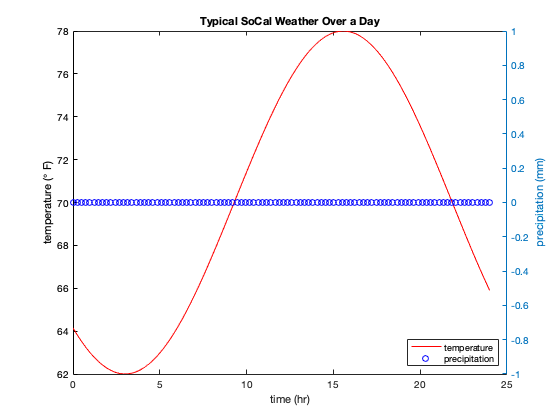

% this saves the figure
saveas(fig_weather,'~/Desktop/SoCalWeather','fig'); %fig is matlab figure format

Loading data from a .mat file is similar. Either the entire file can be loaded, or just specific variables. Any variables loaded will overwrite any variables of the same name in your workspace.

% load just the time and precipitation data
load('~/Desktop/SoCalWeather.mat','t_data','precipitation_data');

## Section 11: Debugging

You will likely spend as much time debugging your code as creating it. Matlab has some nice tools to help you debug your scripts. Here's a list of some Matlab specific ones:

- Red, orange ticks to the right of the editor window - gives error/warning messages

- Run section by section

- Add breakpoints - click ticks to the left of the editor, program will pause at that line

- 'Run and time' - will give a breakdown of your code and which parts are taking the most time

In any language, there are some basic methods you can try if you're stuck:

- Print everything - make your program talk to you, display lots of output at each line

- SIMPLIFY, SIMPLIFY, SIMPLIFY - break the program into small pieces that work before putting them together <- best practice would be to construct your code this way too

- Come up with simple tests where you know the answer <- you should always do this, regardless of if you know there's a bug already

Many programming languages and editors have a analogy to breakpoints as well.

## Section 12: Google is your friend.

When in doubt on a function, extra options, etc, remember two things:

- Matlab documentation is great. 

- Someone else has had this question before you.

In general, googling 'matlab' with your query will either take you to the documentation for a relevant function (e.g. Matlab sort - function to sort elements of a vector) or point you to places where others have also asked these questions. 

Learning how to Google the CORRECT thing, parsing out which solutions are what you want, and adapting them to your needs is something that takes practice.